clear; close all;

% Demo dynamics
N = 25;
% State space
A = [0.8, 0.1; 0.2, 0.7];
B = [0.1; 1];
C = [1, 0];
% Lifted form
p = zeros(N,1);
W = B; 
for n = 1:N
    p(n,1) = C*W;
    W = A*W;
end
P = tril(toeplitz(p));

% Reference
ur = randn(N,1);
r  = P*ur;

% Setup IO-MOLE
dyn_func = @(u)run_linear_siso_ss_dynamics(A, B, C, zeros(2,1), u);
is_mole = CISMOLE(dyn_func, 2, C);

% Initial input trajectory
u0 = 0.01*randn(N,1);

% Number of trials
J = 15;

% Run IO-MOLE
tic;
[ev, ec, yc, uc] = is_mole.run_ismole(r, u0, J);
toc;

Elapsed time is 3.267029 seconds.


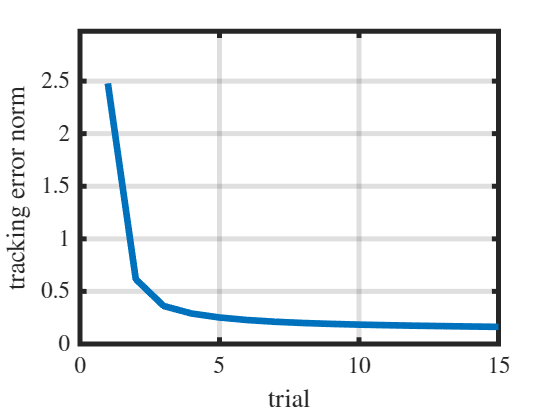


% Plot error norms
figure;
plot(ev);
xlabel('trial');
ylabel('tracking error norm');
ylim([0, ev(1)*1.2]);

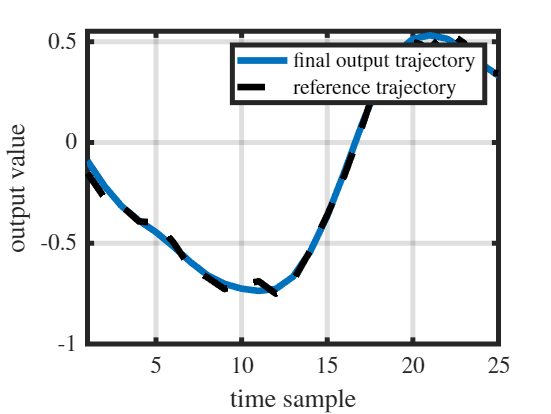


% Plot reference and final output trajectory
figure;
plot(yc{end,1}); hold on;
plot(r, '--', 'Color', 'black');
xlabel('time sample');
ylabel('output value');
legend('final output trajectory', 'reference trajectory');
xlim([1,N]);